## 2. Classification of Deterministic Data

**2.1 Periodic signals**

Periodic signals are defined as those whose waveform repeats exactly at regular time intervals. 

Time interval for one cycle is the period Tp (sec), its reciprocal frequency 1/Tp (Hz).

Sine signal; Triangular signal; Arbitrary signal

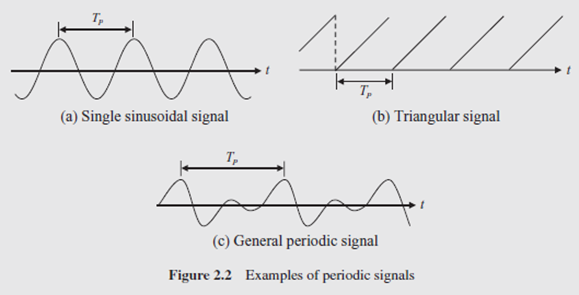

In case of (b), (c), the time domain shape is decomposed into infinite number of freq. components. As an example, the frequency domain representation of the amplitudes of the triangular wave (b) with a period of TP = 2 seconds is shown in the figure, where components in the frequency domain consist of the fundamental frequency 1/TP and its harmonics 2/TP , 3/TP, . . . , i.e. all frequency components are ‘harmonically related’.

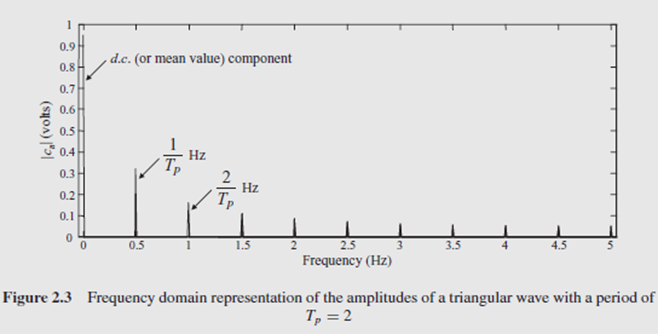

However, there is hardly ever a perfect periodic signal in reality even if the signal is carefully controlled. An example may be telephone tone: keypad ‘8’ is designed to have frequency components at 852 Hz and 1336 Hz only. This is transformed into the frequency domain: (b) (linear scale) and (c) (log scale). On a linear scale, it seems to be composed of the two frequencies. However, there are in fact, many other frequency components that may result if the signal is not perfectly periodic, and this can be seen by plotting the transform on a log scale.

From the examples, it follows that most periodic signals in practical situations are not ‘truly’ periodic, but are ‘almost’ periodic. **In ‘almost periodic’ case, the frequency components other than the peaks do exist in practice.**

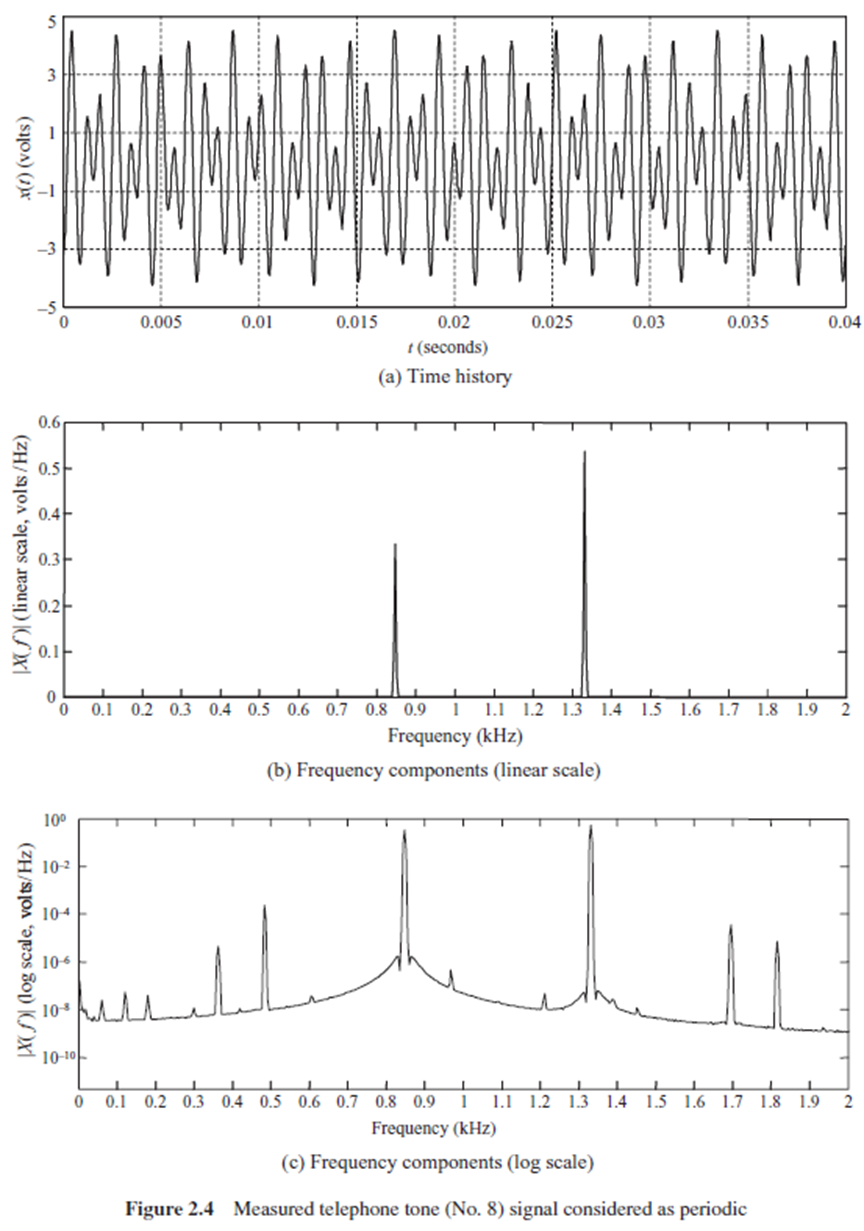

**2.2 Almost periodic signals**

Consider

                              

If p1/p2 is rational (ratio of integer), x becomes periodic with period of smaller of 1/p1 & 1/p2.

Otherwise, it never repeats.

**Example 2.1: two sine functions and its FFT.**

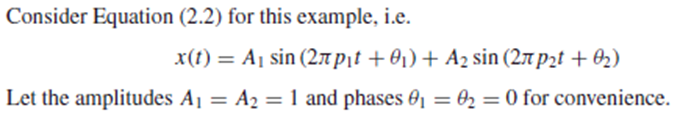

When p1, p2 = 1.4, 1.5, least common multiple of periods 1/1.4, 1/1.5 is 10. Then, the period of resulting signal becomes 10, and p is 0.1Hz. Therefore, we need to set period at this value.

When p1=sqrt(2), the period of resulting signal does not exist although it apparently looks like exist.

Let’s check this is true using the FFT technique that will be explained later.

When 1.4, 1.5, we find clearly the two frequency.

When sqrt(2), 1.5, we find 1.5 clearly but not for sqrt(2). Instead we have 

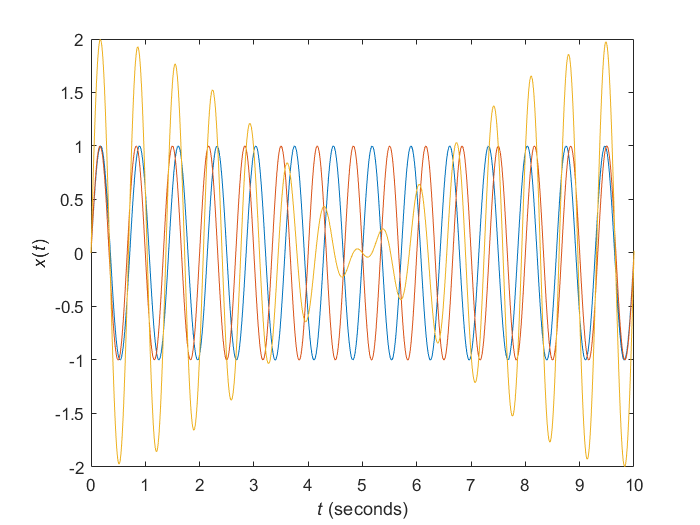

%case 1: p1=1.4; case 2: p1=sqrt(2); 
A1=1; A2=1; Theta1=0; Theta2=0; p1=1.4; p2=1.5;
t=[0:0.01:30]; 
x1=A1*sin(2*pi*p1*t+Theta1); x2=A2*sin(2*pi*p2*t+Theta2); x=x1+x2;
plot(t,[x1' x2' x']); xlabel('\itt\rm (seconds)'); xlim([0 10]); ylabel('\itx\rm(\itt\rm)')

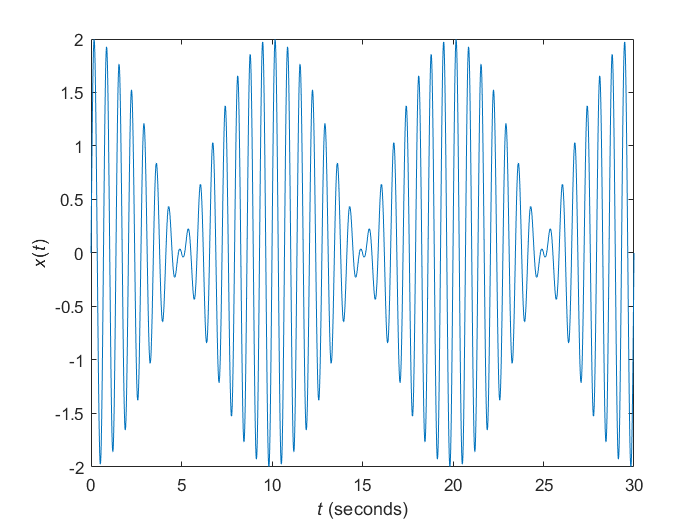

plot(t, x); xlabel('\itt\rm (seconds)'); ylabel('\itx\rm(\itt\rm)')

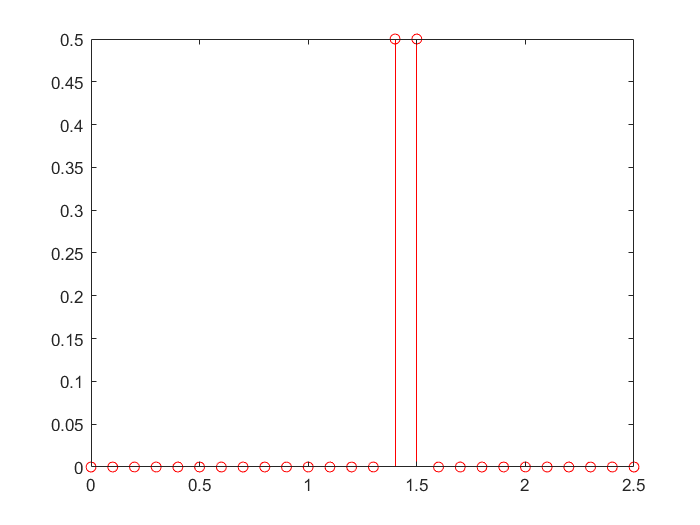


% FFT
fs=5; T=10; t=0:1/fs:T-1/fs;
x1=A1*sin(2*pi*p1*t+Theta1); x2=A2*sin(2*pi*p2*t+Theta2); x=x1+x2;
N=length(x); X=fft(x); f=fs*(0:N-1)/N; 
figure(2); stem(f(1:N/2+1), abs(X(1:N/2+1)/fs/T), 'r'); 